# **Welcome to Deci**

**A fluid pipeline to analyze EEG Data with ease**

Written and Compiled by @John Nguyen of Robert Reinhart Lab on 10/15/2018, contact: Akida@bu.edu

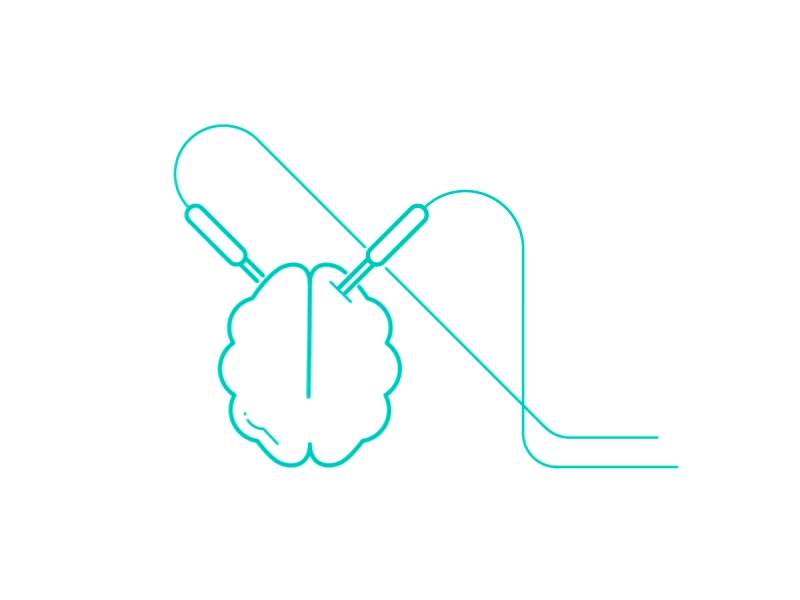

## 0. MainMenu

Deci = [];
Deci.Folder.Raw         = ['C:\Users\User\Desktop\John\AB2\Behav'];              % Raw Data Folder Directory
Deci.SubjectList        = 'gui';                                                  % Cell Array of strings, 'all' or 'gui'
Deci.Step               = 1;                                              % Which Step to implement 1-TD, 2-PP, 3-Art, 4-Analysis, 5-Plot
Deci.Proceed            = false;                                                                  % Continue to next step when current step is done?
Deci.PCom               = false;                                                                  % Activates Parallel Computing for PP and Analysis only
Deci.Folder.Version     = ['C:\Users\User\Desktop\John\AB2\ProcessedData'];        % Output Folder Directory

## 1. Trial Definitions

Deci.DT.Type = 'Manual';                                                                        % Change if need alternative file, otherwise 'Manual' (expfunor2)
Deci.DT.Starts     = {9};                                                                       % Cell Array of Markers for Start codes.
Deci.DT.Ends       = {10};                                                                      % Cell Array of Markers for End codes.
Deci.DT.Markers    = {[21 23] [27 28] [31 32] [51 52]};                                   % Cell Array of Markers for Trial Defs
Deci.DT.Locks      = [14 30 50];                                                                % Num Array for each timelock (usually Stim, Rsp and Fdb Onset )
Deci.DT.Toi        = [-2 3];                                                                    % Time of Interest, be sure to include larger window for freq
Deci.DT.Block.Start   = {11};                                                                     % Cell Array of Markers for Block Starts
Deci.DT.Block.End     = {12};                                                                       % Cell Array of Markers for Block Starts
Deci.DT.Block.Markers = [];                                                                     % Num Array for each type of Block (if empty, Blocks are deliminated chronologically as -1,-2,..etc)

## 2. PreProcessing Steps

Deci.PP.HBP        = 1;                                                                         % Scalar,High-bandpass filter, in Hz.
Deci.PP.DownSample = [];                                                       % Downsample data
Deci.PP.More       = []                                                                         % Add additionall Preprocessing Parameters as according to ft_preprocessing

Deci = struct with fields:
         Folder: [1×1 struct]
    SubjectList: 'gui'
           Step: 1
        Proceed: 0
           PCom: 0
             DT: [1×1 struct]
             PP: [1×1 struct]


## 3. Artifact Rejection

Deci.Art.crittoilim = [-.5 1.5];                                                                % Critical Time Period for trial rejection (Respective to first Lock and Last Lock)
Deci.Art.muscle     = [];                                                                       % if empty, use default muscle parameters
Deci.Art.eog        = [];                                                                       % if empty, use default eog parameters
Deci.Art.PostICAbpf = [];                                                                       % Post ICA broadband pass filter, if desired

## 4. Analysis

#### General Set-Up

Deci.Analysis.Laplace       =false;                                                               % Uses Captrak .bvct file with same name in RawData Folder
Deci.Analysis.Locks         = [1 2 3];                                                          % Which Lock to Analyze        
Deci.Analysis.LocksTitle    = {'Stim Onset','Response Onset','Fdb Onset'};                      % Folder Title to save each Lock as
Deci.Analysis.DownSample    = 500;                                              % Downsample Pre-Analysis
Deci.Analysis.Conditions    = {[21 31 51] [23 31 51] [21 31 52] [23 31 52] ...
                               [21 32 51] [23 32 51] [21 32 52] [23 32 52]};
Deci.Analysis.CondTitle     = {'Opt AB Corr' 'Opt CD Corr' ...
                               'Opt AB Inc'  'Opt CD Inc' ...
                               'Wst AB Corr' 'Wst CD Corr' ...
                               'Wst AB Inc'  'Wst CD Inc' };

#### Time-Frequency Analysis

Deci.Analysis.Freq.do            = true;
Deci.Analysis.Freq.method        = 'wavelet';                                                  % Currently only uses Wavelet Decomp
Deci.Analysis.Freq.foi           = exp(linspace(log(4),log(40),20));                           % Frequency of Interest
Deci.Analysis.Freq.width         = 7 ;                                                         % Width
Deci.Analysis.Freq.gwidth        = 3;                                                          % Gwidth
Deci.Analysis.Freq.Toi           = [-.5 1.5];                                                  % Time Range to save
Deci.Analysis.Freq.Toilim        = [-2 3];                                                     % Time Range to do freq analysis on


#### Cross-Frequency Coupling

% Currently Unavailable
Deci.Analysis.CFC.do = false;
Deci.Analysis.CFC.chanlow =  {'FCz'};
Deci.Analysis.CFC.chanhigh = {'CP3'};
Deci.Analysis.CFC.latencyhigh = [-.2 1];                                                        %no implementation yet to check for edge artifacts so be careful
Deci.Analysis.CFC.latencylow = [-.2 1];
Deci.Analysis.CFC.freqhigh = 'theta';
Deci.Analysis.CFC.freqlow = 'beta';
Deci.Analysis.CFC.timebin = 6;
Deci.Analysis.CFC.methods = {'mi' 'plv'};                                                       % can only currently handle '' or 'mi'(pac)

#### ERP

Deci.Analysis.ERP.do  = false;
Deci.Analysis.ERP.Toi = [-.5 1.5];

## 5. Plotting

**General Set-Up**

Deci.Plot.Lock         = 'Fdb Onset';                   % Which Lock to load                 
Deci.Plot.GrandAverage = false;                                   % Whether or not to grandaverage
Deci.Plot.FreqYScale   = 'linear';                   % Is the Frequency Y scale for Square plots on a linear or log scale?


Deci.Plot.IndexTitle = {'Opt CD Corr' 'Opt GH Corr' ...
                        'Opt AB Inc'  'Opt EF Inc'};

Deci.Plot.Math         = {'[x1 + x3]/2' '[x2 + x4]/2' '[x1 + x2]/2' '[x3 + x4]/2'};           % Condition Math done after Bsl, Condition Indexes are appended on.
Deci.Plot.Draw         = {[1 2 3 4] [5 6] [7 8]};                   % Cell array of Condition Index for each figure
Deci.Plot.Figures      = [true true];                             % Which figure to plot currently
Deci.Plot.Title        = {'All Opt 10 trials' 'Test'};          % Title for each figure
Deci.Plot.Subtitle     = {{'+R' '+P' '-R' '-P'} {'1' '2'}};     % Cell array of strings of subtitles for each Condition

#### Time-Frequency

Deci.Plot.Freq.Foi     = [3 inf];                   % Frequency of Interest
Deci.Plot.Freq.Toi     = [-.5 1.5];                   % Time of Interest
Deci.Plot.Freq.Channel = [{'Pz'}];                   % Channel of Interest
Deci.Plot.Freq.Type    = 'TotalPower';                   % Use 'TotalPower','ITPC' or 'EvokedPower' (Currently Unavailable)
Deci.Plot.Freq.Bsl     = [-.5 -.2];                             % Baseline Correction Time
Deci.Plot.Freq.Topo    =true;
Deci.Plot.Freq.Square  =true;
Deci.Plot.Freq.Wire    =true;

**CFC**

%Currently Unavailable
Deci.Plot.CFC.Topo = true;
Deci.Plot.CFC.Square = true;
Deci.Plot.CFC.Hist = true;
Deci.Plot.CFC.Wire = true;
Deci.Plot.CFC.Roi = 'maxmin';          % Power Range of Interest

**ERP**

Deci.Plot.ERP.Toi = [0 .8];
Deci.Plot.ERP.Channel = {'FCz'};
Deci.Plot.ERP.Bsl = [-.5 -.2];           % Baseline Correction Time
Deci.Plot.ERP.Topo =true;
Deci.Plot.ERP.Wires =true;

#### Behavioral

Deci.Plot.Behv = [];
Deci.Plot.Behv.Source = 'Definition';
% Definition uses .Analysis.Conditions as index reference
% PostArt uses .Plot.IndexTitle as index reference

%Deci.Analysis.Conditions    = {[21 31 51] [23 31 51] [21 31 52] [23 31 52] ...
%                               [21 32 51] [23 32 51] [21 32 52] [23 32 52]};

% Deci.Plot.Behv.Acc.Total = {[1:8] [1:8] };
% Deci.Plot.Behv.Acc.Subtotal = {[1:2] [5:8]};
% Deci.Plot.Behv.Acc.Title = {'Opt Percent' 'Wst Percent'};
% Deci.Plot.Behv.Acc.Subtitle = {'Opt Percent' 'Wst Percent' };
Deci.Plot.Behv.Acc.Total = { [1 3 5 7] [2 4 6 8]};
Deci.Plot.Behv.Acc.Subtotal = { [1 3] [6 8]};

Deci.Plot.Behv.Acc.Title =  {'G Percent' 'N Percent'};
Deci.Plot.Behv.Acc.Subtitle = { 'G Percent' 'N Percent'};


Deci.Plot.Behv.Acc.Block = [1:3];
Deci.Plot.Behv.Acc.Collapse.Trial =false;
Deci.Plot.Behv.Acc.Collapse.Block = true;
Deci.Plot.Behv.Acc.Collapse.Subject = false;
Deci.Plot.Behv.Acc.Collapse.Uneven = 'positional:nans';
Deci.Plot.Behv.Acc.Collapse.Movmean =  false;

Deci.Plot.Behv.RT.Draw = {[1:4] [5:8]};
Deci.Plot.Behv.RT.Title = {'Opt RT' 'Rsp Percent'};
Deci.Plot.Behv.RT.Subtitle = {'Opt' 'Worst'};
Deci.Plot.Behv.RT.Locks = [1 2];

Deci.Plot.Behv.RT.Block = [1:3];
Deci.Plot.Behv.RT.Collapse.Trial =true;
Deci.Plot.Behv.RT.Collapse.Block = true;
Deci.Plot.Behv.RT.Collapse.Subject = true;
Deci.Plot.Behv.RT.Collapse.Uneven = 'positional:nans';

** Extra**

Deci.Plot.Extra.List = true;
Deci.Plot.Extra.Functions = {@QL};
Deci.Plot.Extra.Params = {{}};

**Options**

Deci.Run.Behavior = true;
Deci.Run.Freq =false;
Deci.Run.ERP =false;
Deci.Run.CFC = false;
Deci.Run.Extra = false;

## ** 6. Run**

Deci_Backend(Deci);

Found 239 trials out of 240 for ABProb_Behav_001LB
Saving Preprocessing Data
Found 240 trials out of 240 for ABProb_Behav_003LB_events
Saving Preprocessing Data
Found 238 trials out of 240 for ABProb_Behav_004LB_events
Saving Preprocessing Data
Found 235 trials out of 240 for ABProb_Behav_005LB_events
Saving Preprocessing Data
Found 225 trials out of 240 for ABProb_Behav_006LB
Saving Preprocessing Data
Found 240 trials out of 240 for ABProb_Behav_007LB
Saving Preprocessing Data
Finished DefineTrial at 18.0574
----------------------
